**Solution to Dummy Homework **

*Author*: Pedro Pereira

*Date*: 2016-10-05

*Description*: Solutions to Exercise 1.1 of Nonlinear Control EL2620. This is a dummy homework, just to illustrate the expected reporting style

**Useful material for creating live scripts in matlab**

Read info at [Create Live Scripts](https://www.mathworks.com/help/matlab/matlab_prog/create-live-scripts.html)

**Description of the problem**

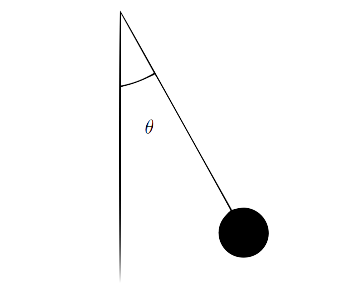

The nonlinear dynamic equation for a pendulum is given by


$$m l \ddot{\theta} = - mg \sin(\theta) - k l \dot{\theta}$$


where $l$ is the length of the pendulum, $m
$ is the mass of the bob, and $\theta$ is the angle subtended by the rod and the vertical axis through the pivot point.

**Constants**

% mass of the bob
m = 1;
% length of pendulum
l = 1;
% acceleration due to gravity
g = 10;
% friction coefficient (we will play with different values)
% k = 1 or k = 2


**Exercise 1.1 a)**

Choose appropriate state variables and write down the state equations.

We can choose $$\theta$$ (standing for the angular position) and $$\omega$$ (standing for the angular velocity) as state variables, with the state equations given by

$\pmatrix{
\dot{\theta}
\cr
\dot{\omega}
}
=
f(\theta,\omega) 
:=
\pmatrix{
\omega 
\cr
- \frac{g}{l} \sin(\theta)
- k l \omega
} $.

We can give different names: $$x_1$$ (standing for the angular position) and $$x_2$$ (standing for the angular velocity) as state variables, with the state equations given by

$\pmatrix{
\dot{x}_1
\cr
\dot{x}_2
}
=
f(x_1,x_2) 
:=
\pmatrix{
x_2
\cr
- \frac{g}{l} \sin(x_1)
- k l x_2
} $.

Another option:

We can choose $$\xi_1$$ (standing for the angular position + angular velocity) and $$\xi_2$$ (standing for the angular position - angular velocity) as state variables, with the state equations given by

$\pmatrix{
\dot{\xi}_1 
\cr
\dot{\xi}_2
}
=
g(\xi_1,\xi_2) 
:=
\pmatrix{
\frac{1}{2}(\xi_1 - \xi_2) 
- \frac{g}{l} 
\sin\left(\frac{1}{2}(\xi_1 + \xi_2) \right)
- k l \frac{1}{2}(\xi_1 - \xi_2)  
\cr
\frac{1}{2}(\xi_1 - \xi_2) 
+ \frac{g}{l} 
\sin\left(\frac{1}{2}(\xi_1 + \xi_2) \right)
+ k l \frac{1}{2}(\xi_1 - \xi_2)  
} $.

**A good choice of state yields "simpler" state equations. **

In defining the vector field in matlab, we introduce the dummy names:

. $z_1$ stands for the angular position (or $\theta$)

. $z_2$ stands for the angular velocity (or $\dot{\theta}$, or $\omega$)

f = @(z1,z2,k) [z2; - g/l*sin(z1) - k*l*z2];

Just for the purpose of display of the vector field (aka, state equations) we introduce symbolic variables

syms x1 x2 k
f(x1,x2,k)

$$ans = \left(\begin{array}{c} x_{2}\\ -10\,\sin\left(x_{1}\right)-k\,x_{2} \end{array}\right)$$

**Exercise 1.1 b)**

Find all equilibria of the system

Definition:  Given state equations $f$, $x^{\star}$ is equilibrium if $f(x^{\star}) = 0$.

Since $f(x_1,x_2) = \left(x_2, - \frac{g}{l} \sin(x_1) - k l x_2\right)$, then $f(x_1^{\star},x_2^{\star}) = 0$ implies that 

1) $x_2^{\star} = 0$ (from first component of vector field)

2) $- \frac{g}{l} 
\sin(x_1^{\star}) 
- 
k l x_2^{\star} 
= 
0 
\Rightarrow 
\sin(x_1^{\star}) = 0 
\Leftrightarrow 
x_1^{\star} = p \pi \forall p \in Z$ (recall 1))

We thus have infinite many equilibria.

**Exercise 1.1 c)**

Description: Linearize the system around the equilibrium points, and determine whether the system equilibria are stable or not (consider $k = 1$ in the case numerical calculations are required)

It suffices to check for equilibria $(x_1^{\star},x_2^{\star}) \in \{ (0,0), (\pi,0) \}$ (explain why!).

**Exercise 1.1 c) Alternatice 1 (preferred solution)**

Do everything analytically


$$A(x)
= 
\frac{d f(x)}{dx}
=
\pmatrix{
\frac{\partial f_1(x_1,x_2)}{\partial x_1}
&
\frac{\partial f_1(x_1,x_2)}{\partial x_2}
\cr
\frac{\partial f_2(x_1,x_2)}{\partial x_1}
&
\frac{\partial f_2(x_1,x_2)}{\partial x_2}
}
=
\pmatrix{
0
&
1
\cr
-\frac{g}{l} \cos(x_1)
&
- k l
}$$


Thus, for $x^{\star} = (x_1^{\star}, x_2^{\star}) = (0,0)$


$$A(x^{\star})
= 
\pmatrix{
0
&
1
\cr
-\frac{g}{l}
&
- k l
}
\Rightarrow
\cdots
\Rightarrow
eigenavalues(A(x^{\star}))
\in 
\left\{
- \frac{kl}{2}
+
\sqrt{
\left(\frac{kl}{2}\right)^{2}
-
\frac{g}{l}
}
,
- \frac{kl}{2}
-
\sqrt{
\left(\frac{kl}{2}\right)^{2}
-
\frac{g}{l}
}
\right\}$$


which means that $x^{\star} = (x_1^{\star}, x_2^{\star}) = (0,0)$ is stable, since the eigenvalues are on LHP (you would need to argue a bit more on why the eigenvalues are on the LHP).

On the other hand, for $x^{\star} = (x_1^{\star}, x_2^{\star}) = (\pi,0)$


$$A(x^{\star})
= 
\pmatrix{
0
&
1
\cr
\frac{g}{l}
&
- k l
}
\Rightarrow
\cdots
\Rightarrow
eigenavalues(A(x^{\star}))
\in 
\left\{
- \frac{kl}{2}
+
\sqrt{
\left(\frac{kl}{2}\right)^{2}
+
\frac{g}{l}
}
,
- \frac{kl}{2}
-
\sqrt{
\left(\frac{kl}{2}\right)^{2}
+
\frac{g}{l}
}
\right\}$$


which means that $x^{\star} = (x_1^{\star}, x_2^{\star}) = (\pi,0)$ is ubstable, since one of the eigenvalues is on the RHP (you would need to argue a bit more on why one of the eigenvalues is on the RHP).

**Exercise 1.1 c) Alternatice 2**

Do symbolic calculations with the help of matlab

% create symbolic variables x1, x2 and k (you could let g and l be symbolic variables as well)
syms x1 x2 k
A = jacobian((f(x1,x2,k)), [x1, x2]) 

$$A = \left(\begin{array}{cc} 0 & 1\\ -10\,\cos\left(x_{1}\right) & -k \end{array}\right)$$

$(x_1^{\star}, x_2^{\star}) = (0,0)$ is stable because eigenvalues are on LHP

% one may check the eigenvales for arbitrary k
A1 = subs(A, {x1, x2}, {0, 0});
eig(A1)

$$ans = \left(\begin{array}{c} -\frac{k}{2}-\frac{\sqrt{k^{2}-40}}{2}\\ \frac{\sqrt{k^{2}-40}}{2}-\frac{k}{2} \end{array}\right)$$

% or one may check the eigenvales for k = 1, for example
A1 = subs(A, {x1, x2, k}, {0, 0 1});
eig(A1)

$$ans = \left(\begin{array}{c} -\frac{1}{2}-\frac{\sqrt{39}\,\mathrm{i}}{2}\\ -\frac{1}{2}+\frac{\sqrt{39}\,\mathrm{i}}{2} \end{array}\right)$$

% print eigenvalues in ''easier'' to read format
double(eig(A1))

ans =   -0.5000 - 3.1225i
  -0.5000 + 3.1225i


$(x_1,x_2) = (\pi,0)$ is unstable because eigenvalues are not on LHP:

% one may check the eigenvales for arbitrary k
A2 = subs(A, {x1, x2}, {pi, 0});
eig(A2)

$$ans = \left(\begin{array}{c} -\frac{k}{2}-\frac{\sqrt{k^{2}+40}}{2}\\ \frac{\sqrt{k^{2}+40}}{2}-\frac{k}{2} \end{array}\right)$$

% or one may check the eigenvales for k = 1, for example
A2 = subs(A, {x1, x2, k}, {pi, 0, 1});
eig(A2)

$$ans = \left(\begin{array}{c} -\frac{\sqrt{41}}{2}-\frac{1}{2}\\ \frac{\sqrt{41}}{2}-\frac{1}{2} \end{array}\right)$$

% print eigenvalues in ''easier'' to read format
double(eig(A2))

ans =    -3.7016
    2.7016


**Exercise 1.1 d)**  (this is not in the Exercise: it is just to further illustrate how to report)

Simulate system with $k =1$ and $k = 2$ and with initial condition $x(0) = (x_1(0),x_2(0)) = (0.5\pi,0.1)$. Discuss the results.

**Exercise 1.1 d)  ALTERNATIVE 1**

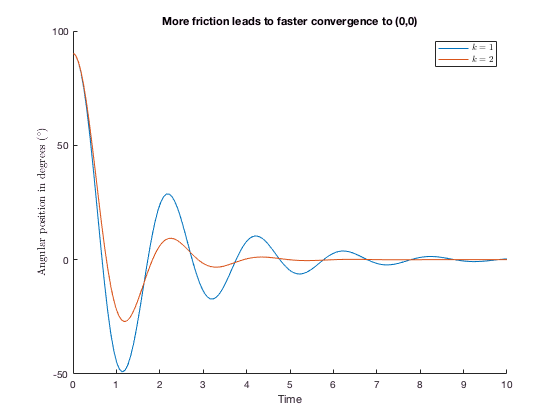

% initial time instant
t0 = 0;
% final time instant
tF = 10;
% initial condition
x0 = [0.5*pi;0.1];

hold on
for friction = [1,2]
    % check documentation for ode45
    % remark: in general a vector field is a function of time and state, aka (t,x)
    [time_vector,state_vector] = ode45(@(t,x) f(x(1),x(2), friction),[t0 tF],x0);
    % angular position from radians to degrees
    plot(time_vector,state_vector(:,1)*180/pi)
end

% label axis
xlabel('Time')
ylabel('Angular position in degrees ($^\circ$)','interpreter','latex')
% legend for the plot
h = legend('$k=1$','$k=2$');
set(h,'interpreter','latex')
% title with the DISCUSSION
title('More friction leads to faster convergence to (0,0)')

**Exercise 1.1 d)  ALTERNATIVE 2**

Using simulink

% close previous figure
close all

for friction = [1,2]
    
    k = friction;
    % simulate model described in PendulumSimulation.slx
    % in this model, k is a parameter, which as been set to the same value
    % as friction
    % 
    % if you wish, change step size, so that plot is not so cluncky 
    sim('PendulumSimulation.slx');

    % vector with time instants (sec)
    time_vector = State.Time;
    % vector with state
    state_vector = State.Data;

    hold on
    plot(time_vector,state_vector(:,1)*180/pi)
end

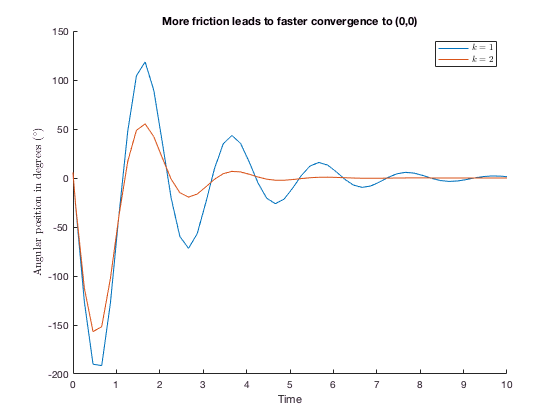


% label axis
xlabel('Time')
ylabel('Angular position in degrees ($^\circ$)','interpreter','latex')
% legend for the plot
h = legend('$k=1$','$k=2$');
set(h,'interpreter','latex')
% title with the DISCUSSION
title('More friction leads to faster convergence to (0,0)')

**WARNINGS: **Always check documentation of functions

Example: select ode45 with cursor and press F1

**WARNINGS: **Latex

For quick typesetting, write "$", then write in latex, and when you close with "$", the latex expression is rendered. 

**WARNINGS:  **Other problems

Google is your friend